[panel, fsp] = audioread("no_cancel_new_panel.wav");

[foam, fsf] = audioread("no_cancel_new_foam.wav");


t = (1:length(panel)) / fsp;
t = t';
size(t)

ans =       480256           1


size(panel)

ans =       480256           1


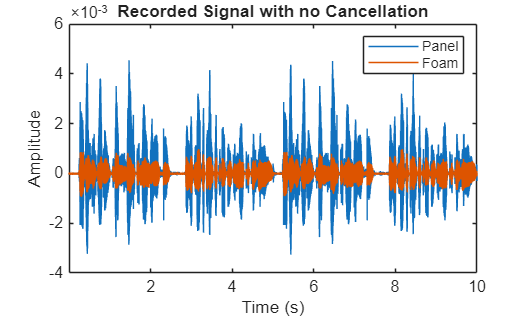

figure
plot(t, panel)
hold on
plot(t, foam) 
legend("Panel", "Foam")
xlim([t(1), t(end)])
title("Recorded Signal with no Cancellation")
xlabel("Time (s)")
ylabel("Amplitude")

ms = @(x) mean(x.^2);
mse = @(x, y) mean((x - y).^2);

panel_ms = ms(panel)

panel_ms = 2.9661e-07

foam_ms = ms(foam)

foam_ms = 4.7807e-08


panel_rms = rms(panel)

panel_rms = 5.4462e-04

foam_rms = rms(foam)

foam_rms = 2.1865e-04